# Try more channels input*

change Fp2 to AF3

maxEpochs = 30;
slice = 512*4;
rng default

ds = load('LabledData\raw_labled.mat', 'ls');
ds = ds.ls.Labels;
lables = ds.detect_blinks;
dir = ds.Properties.RowNames;


Ds = {};
for i = 1:numel(dir)    
    raw_data = csvread(dir{i},1,1);
    filtered_data = hl_filter(raw_data(:,[1,2,31]));
    lable = lables(i);
    masked = getmask({filtered_data,lable{1,1}});
    Ds{i} = masked;  
end

chopedDs = {};

for i = 1:numel(Ds)
    for j = 1:slice:size(Ds{i}{1},1)-2*slice
        chopedDs{end+1} = {Ds{i}{1}(j:j+slice,:).',Ds{i}{2}(j:j+slice,:).'};        
    end
end
XTrain = {};
YTrain = {};

for i = 1:numel(chopedDs)
    XTrain{end+1} = chopedDs{i}{1};
    YTrain{end+1} = chopedDs{i}{2};
end


XTrain = 1×1465 cell array
    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    {3×2049 double}    

YTrain = 1×1465 cell array
    {[blink    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[blink    …    ]}    {[n/a    …    ]}    {[blink    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[blink    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[blink    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[n/a    …    ]}    {[blink    …    ]}    {[n/a    …    ]}    {[n/a    …    ]} 

[trainIdx,~,testIdx] = dividerand(numel(XTrain),0.7,0,0.3);

XTest = XTrain(testIdx);
YTest = YTrain(testIdx);
XTrain = XTrain(trainIdx);
YTrain = YTrain(trainIdx);
trainDs={};testDs={};
for i = 1:numel(XTrain)
    trainDs{end+1} = [{XTrain{i}},{YTrain{i}}];

end
for i = 1:numel(XTest)
    testDs{end+1} = [{XTest{i}},{YTest{i}}];
end

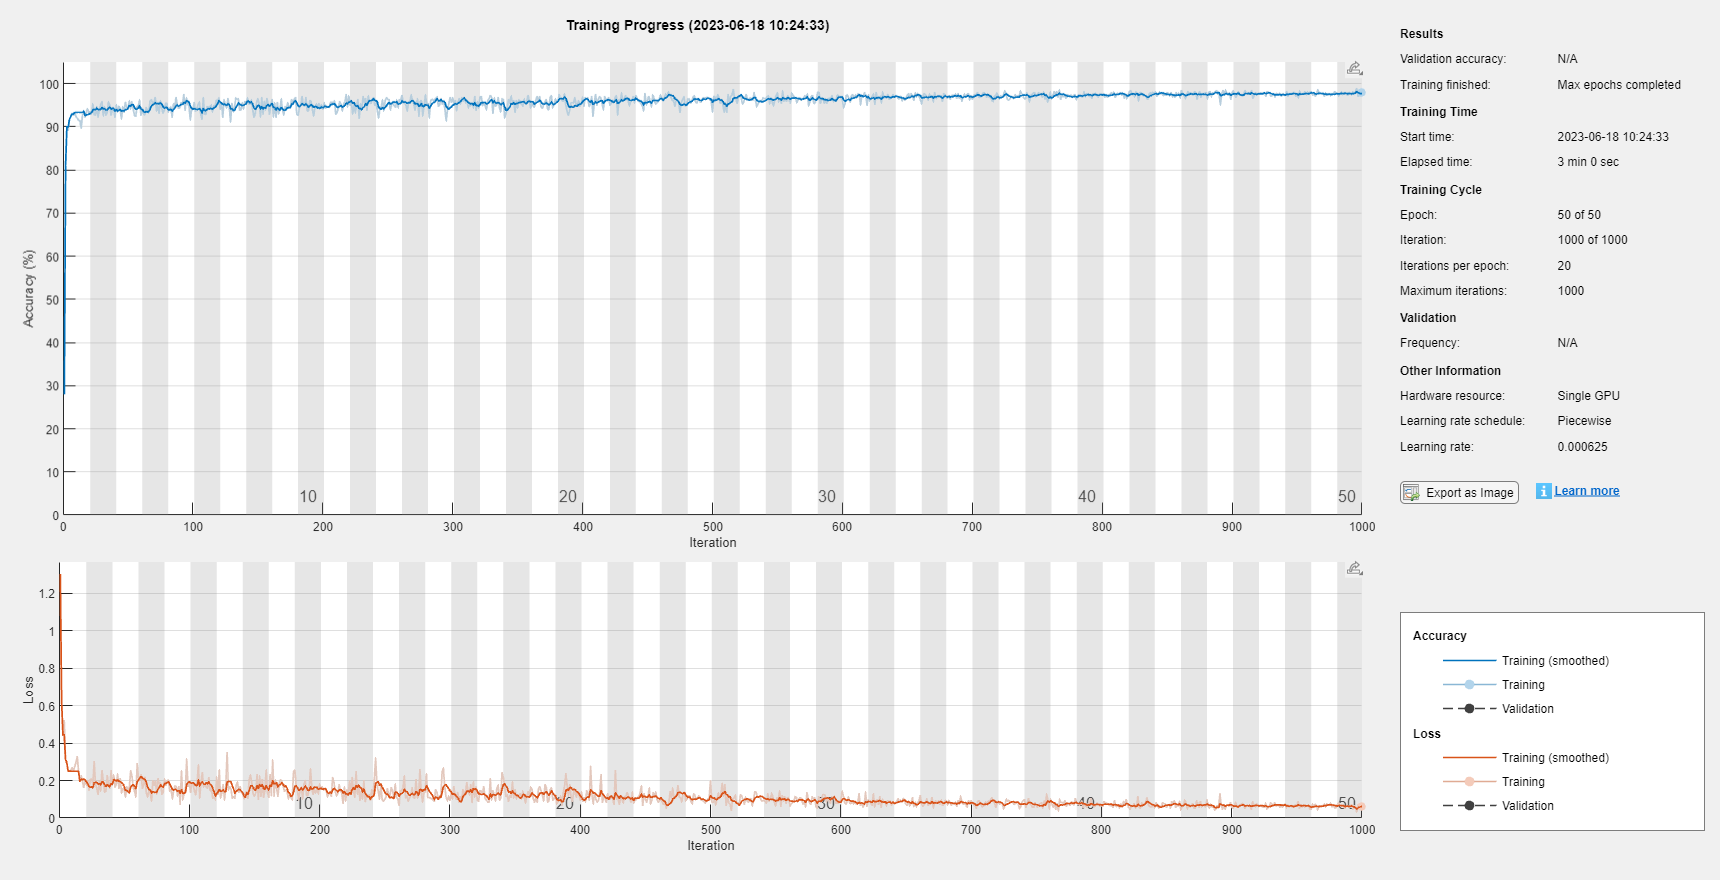

layers = [ ...
    sequenceInputLayer(3)
    bilstmLayer(100,'OutputMode','sequence')
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',50, ...
    'InitialLearnRate',0.01, ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateSchedule','piecewise', ...
    'GradientThreshold',1, ...
    'Plots','training-progress',...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true);


lstmNet = trainNetwork(XTrain,YTrain,layers,options);

for i=1
biLstmActivations = activations(lstmNet, XTrain{i}, 2);
disp(biLstmActivations{1});
end

   -0.1468   -0.2544   -0.3410   -0.4069   -0.4569   -0.4947   -0.5235   -0.5459   -0.5636   -0.5780   -0.5901   -0.6003   -0.6091   -0.6169   -0.6237   -0.6299   -0.6355   -0.6405   -0.6451   -0.6494   -0.6532   -0.6568   -0.6600   -0.6630   -0.6657   -0.6682   -0.6704   -0.6724   -0.6742   -0.6757   -0.6770   -0.6781   -0.6790   -0.6797   -0.6802   -0.6804   -0.6805   -0.6804   -0.6801   -0.6796   -0.6790   -0.6781   -0.6771   -0.6760   -0.6746   -0.6731   -0.6715   -0.6697   -0.6677   -0.6655   -0.6632   -0.6607   -0.6580   -0.6551   -0.6521   -0.6487   -0.6451   -0.6413   -0.6371   -0.6327   -0.6278   -0.6225   -0.6168   -0.6105   -0.6036   -0.5960   -0.5876   -0.5782   -0.5678   -0.5562   -0.5433   -0.5287   -0.5124   -0.4940   -0.4735   -0.4505   -0.4249   -0.3968   -0.3662   -0.3335   -0.2992   -0.2643   -0.2300   -0.1977   -0.1687   -0.1441   -0.1243   -0.1088   -0.0967   -0.0866   -0.0777   -0.0694   -0.0614   -0.0535   -0.0457   -0.0384   -0.0321   -0.0254   -0.0156    0.0017

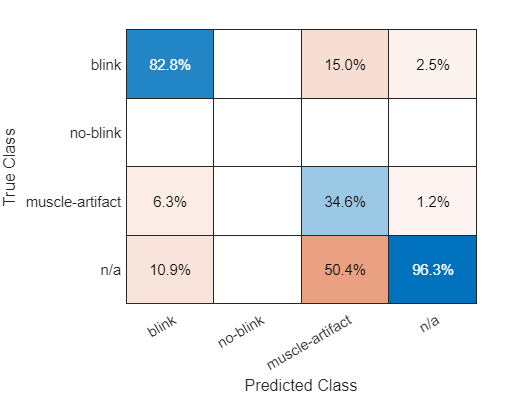

TX = {};
for i = 1:numel(testDs)
    TX{end+1} = testDs{i}{1};
end
Test = classify(rawNet,TX,'MiniBatchSize',50);

TY = [];
Y = [];
for i = 1:numel(testDs)
    TY = [TY;testDs{i}{2}];
    Y = [Y;Test{i}];
end
confusionchart(TY(:),Y(:),'Normalization','column-normalized');

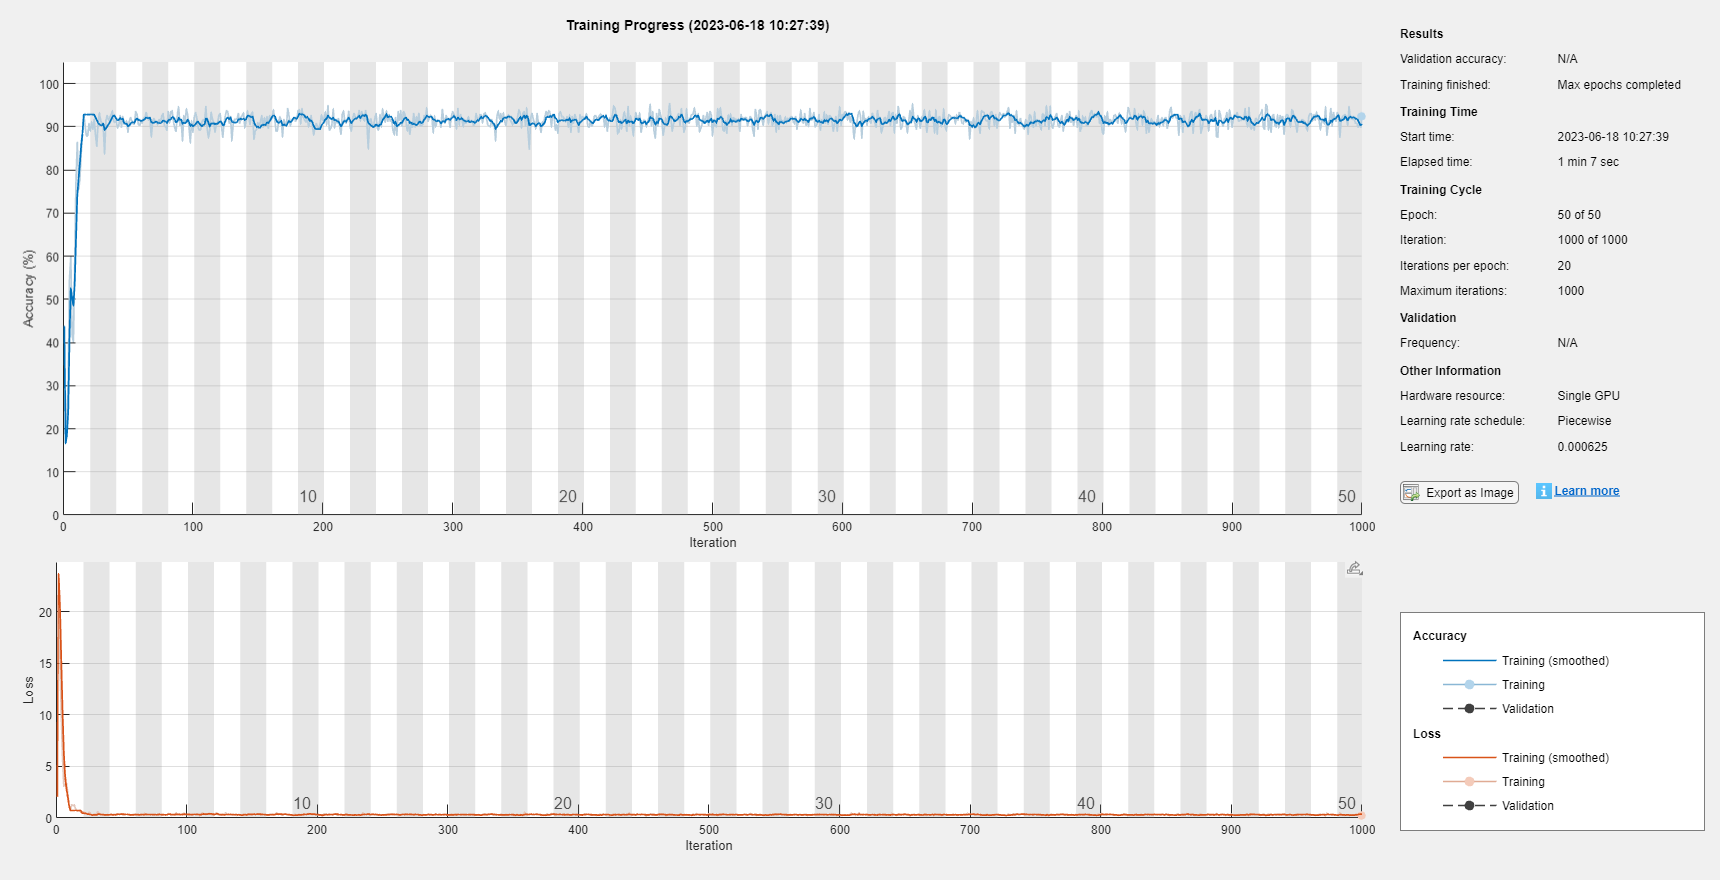

layers = [ ...
    sequenceInputLayer(3)
    fullyConnectedLayer(512)
    fullyConnectedLayer(64)
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',50, ...
    'InitialLearnRate',0.01, ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateSchedule','piecewise', ...
    'GradientThreshold',1, ...
    'Plots','training-progress',...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true);

 
fcNet = trainNetwork(XTrain,YTrain,layers,options);

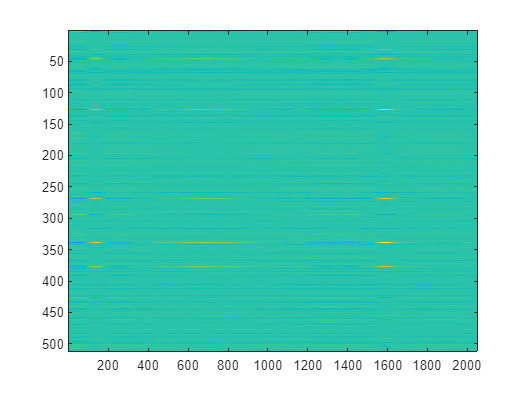

for i=1
fcActivations = activations(fcNet, XTrain{i}, 2);
imagesc(fcActivations{1}(:,:));
end

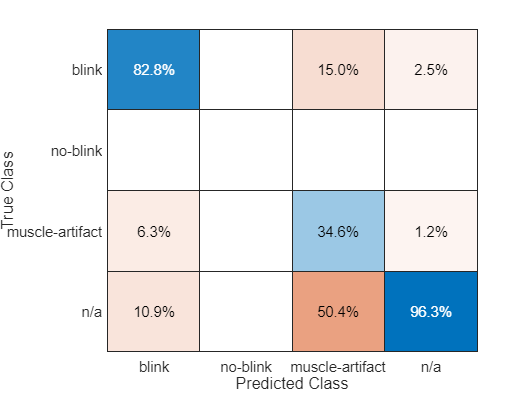

TX = {};
for i = 1:numel(testDs)
    TX{end+1} = testDs{i}{1};
end
Test = classify(rawNet,TX,'MiniBatchSize',50);

TY = [];
Y = [];
for i = 1:numel(testDs)
    TY = [TY;testDs{i}{2}];
    Y = [Y;Test{i}];
end
confusionchart(TY(:),Y(:),'Normalization','column-normalized');

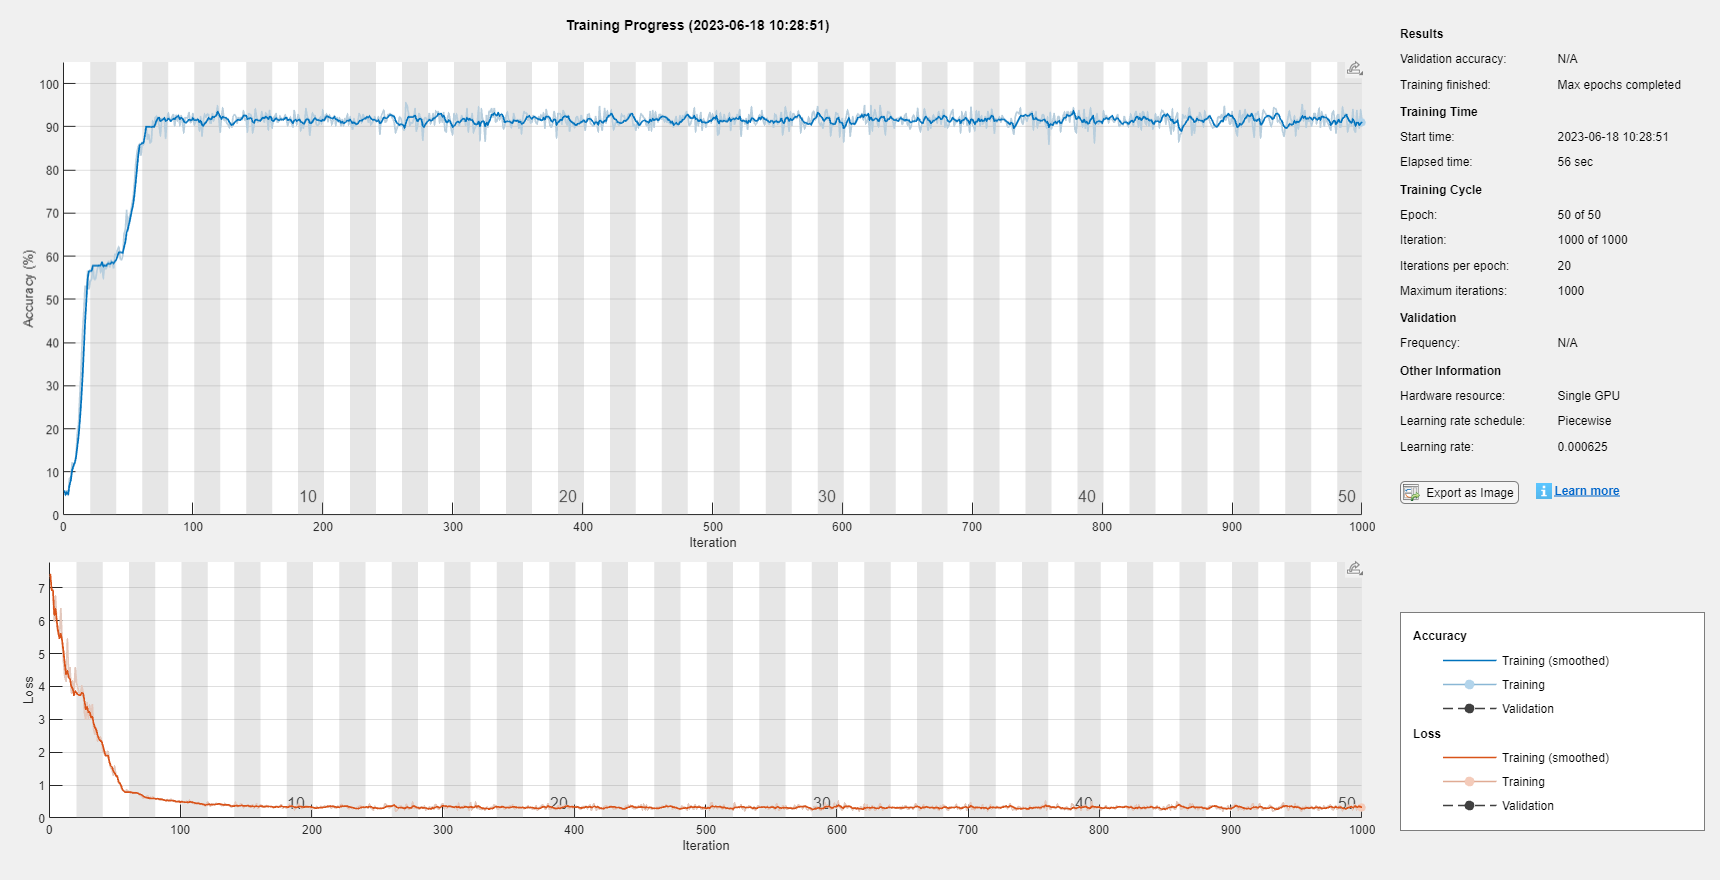

layers = [ ...
    sequenceInputLayer(3)
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',50, ...
    'InitialLearnRate',0.01, ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateSchedule','piecewise', ...
    'GradientThreshold',1, ...
    'Plots','training-progress',...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true);


smallNet = trainNetwork(XTrain,YTrain,layers,options);

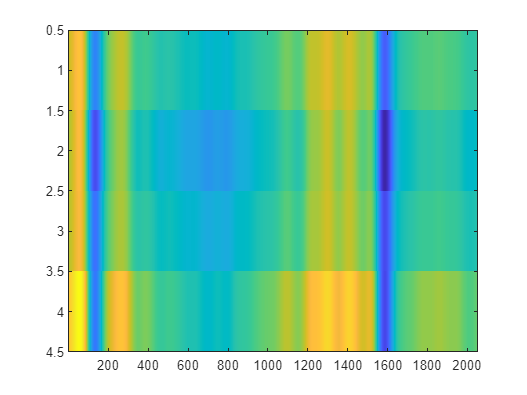

for i=1
smallActivations = activations(smallNet, XTrain{i}, 2);
imagesc(smallActivations{1});
end

TX = {};
for i = 1:numel(testDs)
    TX{end+1} = testDs{i}{1};
end
Test = classify(rawNet,TX,'MiniBatchSize',50);

TY = [];
Y = [];
for i = 1:numel(testDs)
    TY = [TY;testDs{i}{2}];
    Y = [Y;Test{i}];
end
confusionchart(TY(:),Y(:),'Normalization','column-normalized');

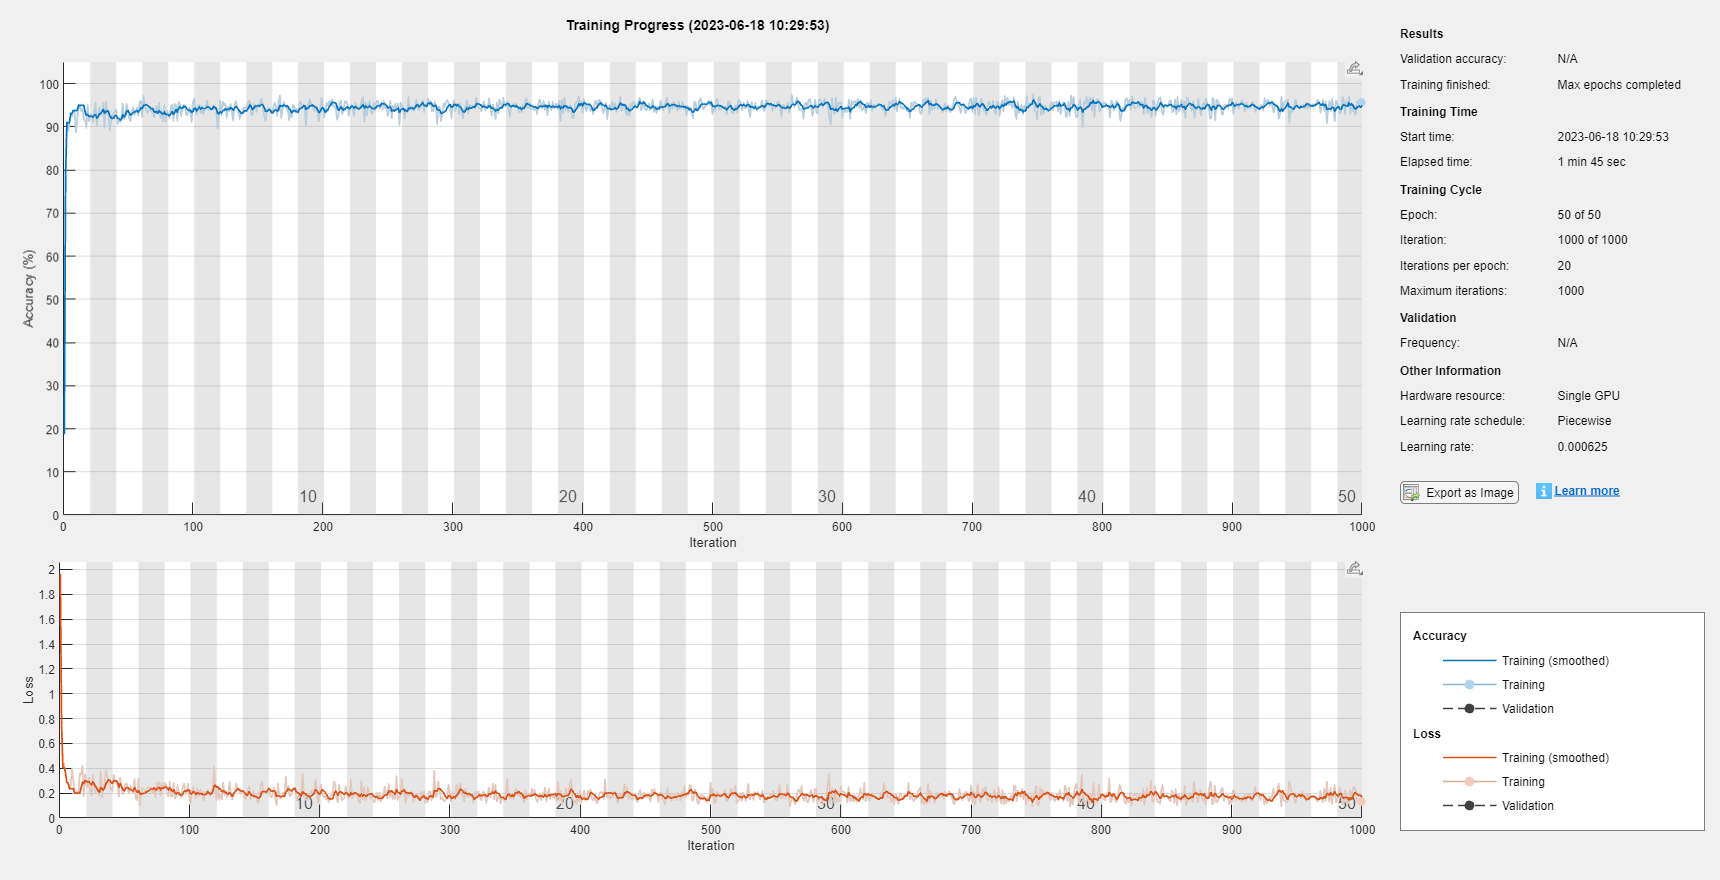

layers = constructTCN();

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',50, ...
    'InitialLearnRate',0.01, ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateSchedule','piecewise', ...
    'GradientThreshold',1, ...
    'Plots','training-progress',...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true);


tcnNet = trainNetwork(XTrain,YTrain,layers,options);

TX = {};
for i = 1:numel(testDs)
    TX{end+1} = testDs{i}{1};
end
Test = classify(rawNet,TX,'MiniBatchSize',50);

TY = [];
Y = [];
for i = 1:numel(testDs)
    TY = [TY;testDs{i}{2}];
    Y = [Y;Test{i}];
end
confusionchart(TY(:),Y(:),'Normalization','column-normalized');

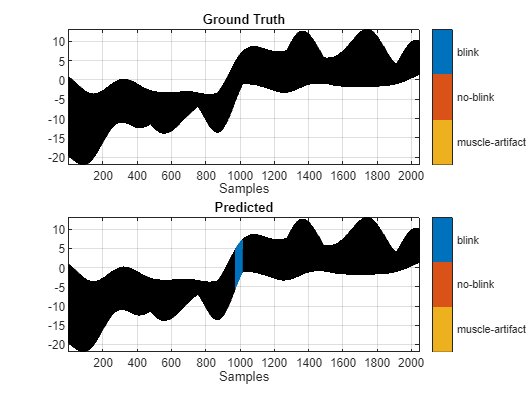

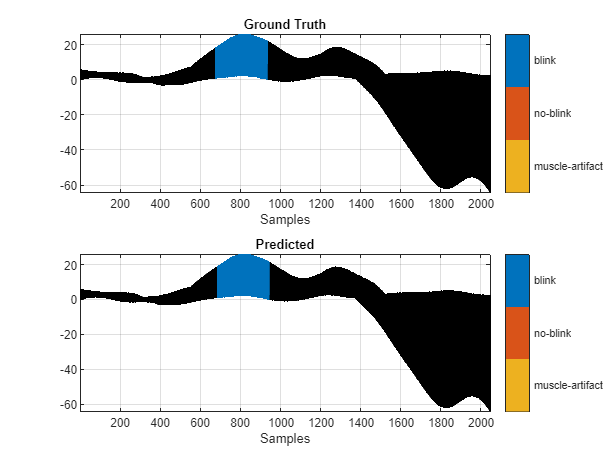

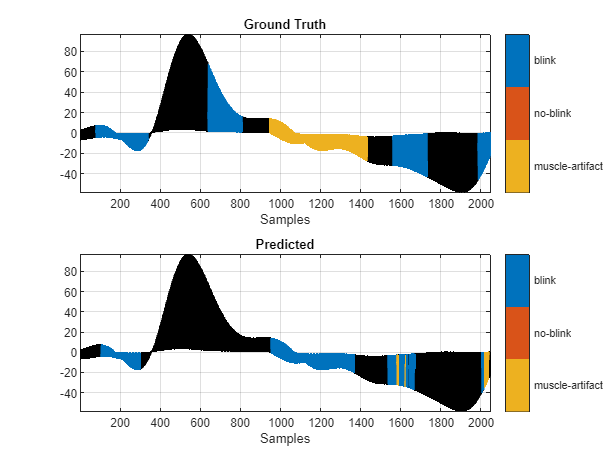

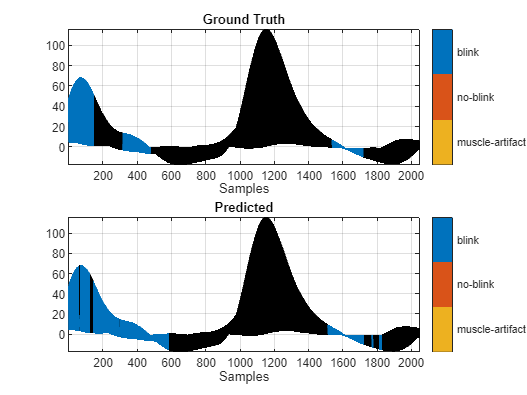

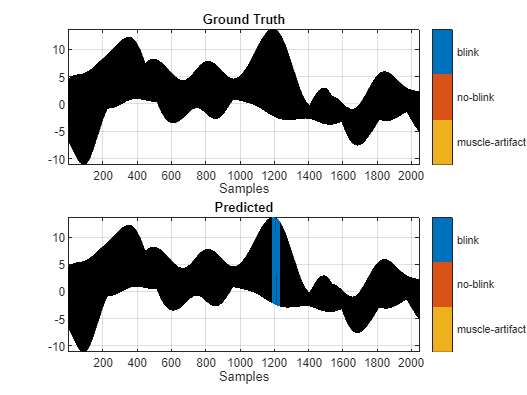

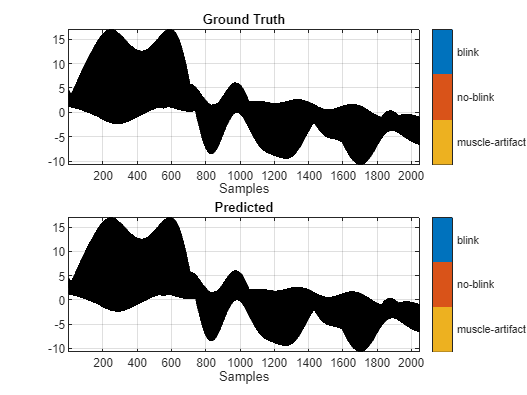

n = 10;
for i = n:n+5
    number = i;
    Test = classify(rawNet,XTest,'MiniBatchSize',50);
    Mtest = signalMask(testDs{number}{2}(1:slice));
    Mtest.SpecifySelectedCategories = true;
    Mtest.SelectedCategories = find(Mtest.Categories ~= "n/a");
    
    figure
    subplot(2,1,1)
    plotsigroi(Mtest,testDs{number}{1}(1:slice))
    title('Ground Truth')
    
    Mpred = signalMask(Test{number}(1:slice));
    Mpred.SpecifySelectedCategories = true;
    Mpred.SelectedCategories = find(Mpred.Categories ~= "n/a");
    
    subplot(2,1,2)
    plotsigroi(Mpred,testDs{number}{1}(1:slice))
    title('Predicted')
end

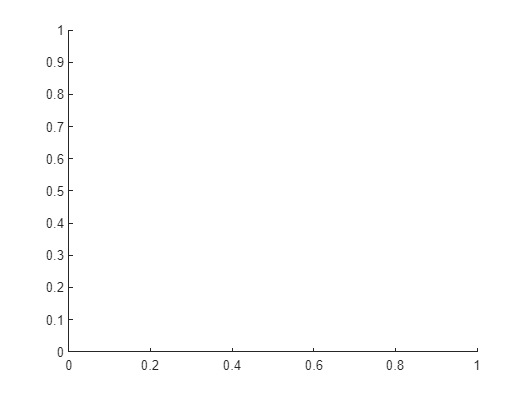

figure
subplot(1,1,1)

n = 38

n = 38

plotsigroi(signalMask(YTrain{n}),XTrain{n})

Error using plotsigroi
Expected X to be a vector.

Error in signalMask/plotsigroi (line 693)
        validateattributes(x,{'numeric'},{'vector'},'plotsigroi','X');